# Feedback Linearization for Nonlinear Quarter Car Model


close all
clearvars
clc


## System Parameters


global M m ks ksn kt bs bt K1 K2

M = 600;
m = 100;
ks = 15000;
ksn = 1000;
kt = 200000;
bs = 1500;
bt = 2000;


## Control Parameters


K1 = 10;
K2 = 11;


## Set up ODE


initial = [0.3;0;0;0];
tspan = 0:0.01:30;

[t,x] = ode45(@quarterCar, tspan, initial);


## Unpack Results


ext = zeros(length(t),1);
ds = zeros(length(t),4);

for i=1:length(t)
    [ds(i,:),ext(i,:)] = quarterCar(t(i),x(i,:));
end

x1 = x(:,1);
x2 = x(:,2);
x3 = x(:,3); 
x4 = x(:,4);

u = ext(:,1);


%% Additional Calculations
yd = 0.2*sin(t);
dyd = 0.2*cos(t);
ddyd = -0.2*sin(t);

y = x1;
dy = x2;

e = y-yd;
de = dy - dyd;

v = ddyd - K1*e - K2*de;


## Plots

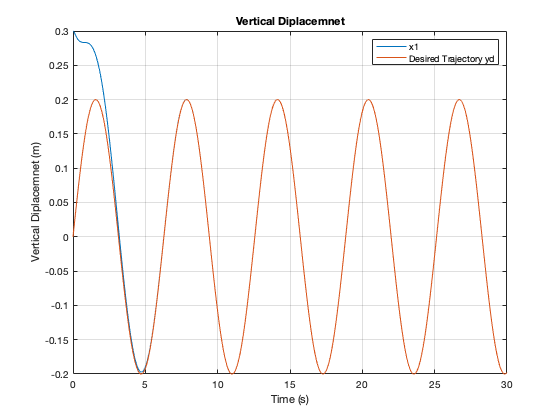


figure(1)
plot(t,x1, t,yd), grid on
title('Vertical Diplacemnet')
xlabel('Time (s)')
ylabel('Vertical Diplacemnet (m)')
legend('x1', 'Desired Trajectory yd')

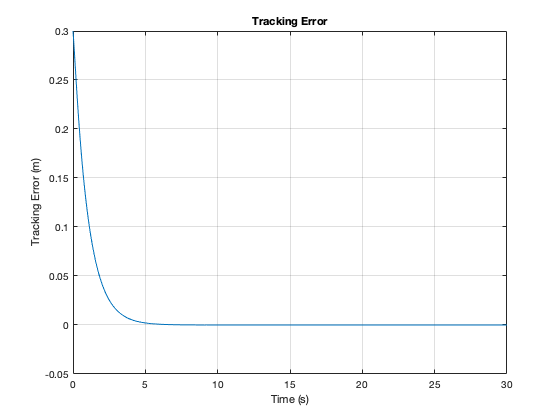


figure(2)
plot(t,e), grid on
title('Tracking Error')
xlabel('Time (s)')
ylabel('Tracking Error (m)')

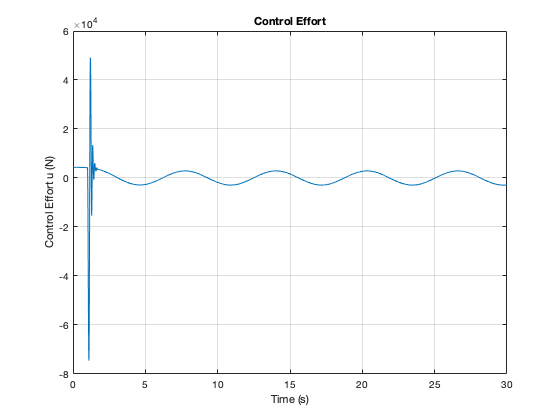


figure(3)
plot(t,u), grid on
title('Control Effort')
xlabel('Time (s)')
ylabel('Control Effort u (N)')

function [x_dot, ext] = quarterCar(t, x)

global M m ks ksn kt bs bt K1 K2


%% Unpack the state variables
x1 = x(1);
x2 = x(2);
x3 = x(3);
x4 = x(4);


%% Road inputs
% w = 1 - cos(8*pi*t);
% dw = 8*pi*sin(8*pi*t);

if t < 1
    w = 0;
elseif t>=1 && t< 1.25 
    w = 1 - cos(8*pi*t);
else
    w = 0;
end

if t < 1
    dw = 0;
elseif t>=1 && t< 1.25 
    dw = 8*pi*sin(8*pi*t);
else
    dw = 0;
end


%% Controller Design
yd = 0.2*sin(t);
dyd = 0.2*cos(t);
ddyd = -0.2*sin(t);

y = x1;
dy = x2;

e = y-yd;
de = dy - dyd;

v = ddyd - K1*e - K2*de;

u = M*(v-1/M*(-(ks*(x1-x3) + ksn*(x1 - x3)^3)-bs*(x2 - x4)));


%% State Equations
x1_dot = x2;
x2_dot = (-(ks*(x1-x3) + ksn*(x1 - x3).^3)-bs*(x2 - x4) + u)/M;
x3_dot = x4;
x4_dot = (ks*(x1-x3) + ksn*(x1 - x3)^3.+bs*(x2 - x4)-kt*(x3 - w)-bt*(x4 - dw) - u)/m;


%% Pack output
x_dot = [x1_dot; x2_dot; x3_dot; x4_dot];
ext = [u];

end